clc; clear; close all; addpath('z_toolbox');
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step7_IEDtw_Yeo7', 'IEDtw_delays_rate_Yeo7.mat'));
delaysYeo7Mean = delaysYeo7Mean(1:7, 1:7, :);
% Create figure for network-specific delay visualization
withinDelay = []; betweenDelay = [];
for netID = 1:7
    % within network
    withinDelay = [withinDelay; squeeze(delaysYeo7Mean(netID, netID, :))];
    % between network
    for n = 1:7
        if n ~= netID
            betweenDelay = [betweenDelay; squeeze(delaysYeo7Mean(netID, n, :))];
            betweenDelay = [betweenDelay; squeeze(delaysYeo7Mean(n, netID, :))];
        end
    end
end
withinDelay(isnan(withinDelay)) = [];
betweenDelay(isnan(betweenDelay)) = [];
withinStr = cell(length(withinDelay), 1);
for n = 1:length(withinStr)
    withinStr{n, 1} = 'intra-network';
end
betweenStr = cell(length(betweenDelay), 1);
for n = 1:length(betweenDelay)
    betweenStr{n, 1} = 'inter-network';
end
data = [withinDelay; betweenDelay];
Str = [withinStr; betweenStr];
figure('Units', 'centimeters', 'Position', [5, 5, 26, 20]);
subplot(2, 2, 1);
vs = violinplot(data, Str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'intra-network', 'inter-network'}, ...
    'ViolinColor', [0.8, 0.4, 0.4; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.3, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = withinDelay; y = betweenDelay;
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' CliffDelta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 2.4259e-26 z = -10.6192 CliffDelta = -0.48041 df = 1738


clear;
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step7_IEDtw_Yeo7', 'IEDtw_delays_rate_Yeo7.mat'));
rateYeo7Mean = rateYeo7Mean(1:7, 1:7, :);
% Create figure for network-specific rate visualization
withinRate = []; betweenRate = [];
for netID = 1:7
    % within network
    withinRate = [withinRate; squeeze(rateYeo7Mean(netID, netID, :))];
    % between network
    for n = 1:7
        if n ~= netID
            betweenRate = [betweenRate; squeeze(rateYeo7Mean(n, netID, :))];
            betweenRate = [betweenRate; squeeze(rateYeo7Mean(netID, n, :))];
        end
    end
end
betweenRate(isnan(betweenRate)) = [];
withinRate(isnan(withinRate)) = [];
withinStr = cell(length(withinRate), 1);
for n = 1:length(withinStr)
    withinStr{n, 1} = 'intra-network';
end
betweenStr = cell(length(betweenRate), 1);
for n = 1:length(betweenRate)
    betweenStr{n, 1} = 'inter-network';
end
data = [withinRate; betweenRate];
Str = [withinStr; betweenStr];
subplot(2, 2, 2);
vs = violinplot(data, Str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'intra-network', 'inter-network'}, ...
    'ViolinColor', [0.4, 0.4, 0.7; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.3, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]);
ylabel('IED-TW Rate (n/min)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = withinRate; y = betweenRate;
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' CliffDelta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 5.7837e-12 z = 6.8849 CliffDelta = 0.3115 df = 1738


clear;
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step7_IEDtw_Yeo7', 'NAxc_delays_rate_Yeo7.mat'));
delaysYeo7Mean = NAxcD_Yeo7Mean(1:7, 1:7, :);
% Create figure for network-specific delay visualization
withinDelay = []; betweenDelay = [];
for netID = 1:7
    % within network
    withinDelay = [withinDelay; squeeze(delaysYeo7Mean(netID, netID, :))];
    % between network
    for n = 1:7
        if n ~= netID
            betweenDelay = [betweenDelay; squeeze(delaysYeo7Mean(netID, n, :))];
            betweenDelay = [betweenDelay; squeeze(delaysYeo7Mean(n, netID, :))];
        end
    end
end
withinDelay(isnan(withinDelay)) = [];
betweenDelay(isnan(betweenDelay)) = [];
withinStr = cell(length(withinDelay), 1);
for n = 1:length(withinStr)
    withinStr{n, 1} = 'intra-network';
end
betweenStr = cell(length(betweenDelay), 1);
for n = 1:length(betweenDelay)
    betweenStr{n, 1} = 'inter-network';
end
data = [withinDelay; betweenDelay];
Str = [withinStr; betweenStr];
subplot(2, 2, 3);
vs = violinplot(data, Str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'intra-network', 'inter-network'}, ...
    'ViolinColor', [0.8, 0.4, 0.4; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.3, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]);
ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = withinDelay; y = betweenDelay;
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' CliffDelta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 2.57e-93 z = -20.4914 CliffDelta = -0.92182 df = 1762


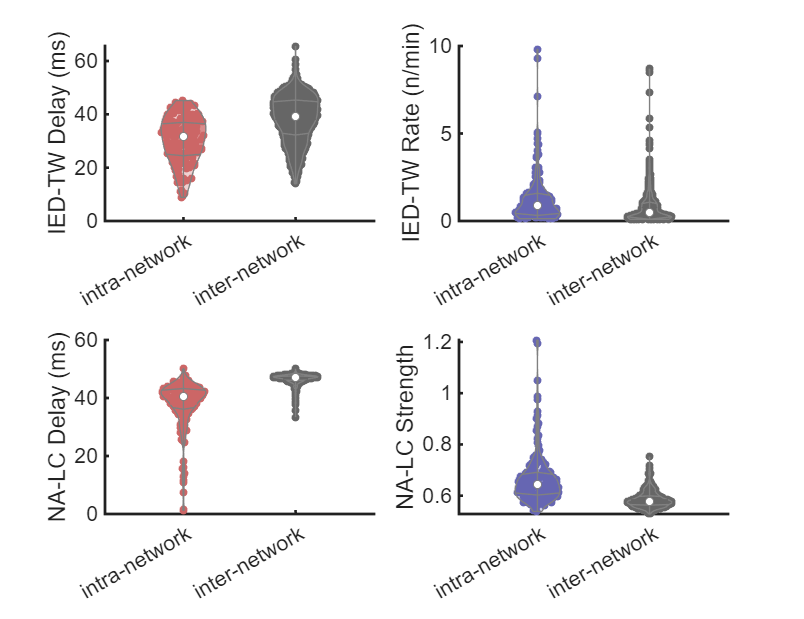

clear;
load(fullfile('step7_IEDtw_Yeo7', 'NAxc_delays_rate_Yeo7.mat'));
rateYeo7Mean = NAxcR_Yeo7Mean(1:7, 1:7, :);
% Create figure for network-specific rate visualization
withinRate = []; betweenRate = [];
for netID = 1:7
    % within network
    withinRate = [withinRate; squeeze(rateYeo7Mean(netID, netID, :))];
    % between network
    for n = 1:7
        if n ~= netID
            betweenRate = [betweenRate; squeeze(rateYeo7Mean(n, netID, :))];
            betweenRate = [betweenRate; squeeze(rateYeo7Mean(netID, n, :))];
        end
    end
end
betweenRate(isnan(betweenRate)) = [];
withinRate(isnan(withinRate)) = [];
withinStr = cell(length(withinRate), 1);
for n = 1:length(withinStr)
    withinStr{n, 1} = 'intra-network';
end
betweenStr = cell(length(betweenRate), 1);
for n = 1:length(betweenRate)
    betweenStr{n, 1} = 'inter-network';
end
data = [withinRate; betweenRate];
Str = [withinStr; betweenStr];
subplot(2, 2, 4);
vs = violinplot(data, Str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'intra-network', 'inter-network'}, ...
    'ViolinColor', [0.4, 0.4, 0.7; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.3, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]);
ylabel('NA-LC Strength');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = withinRate; y = betweenRate;
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' CliffDelta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 2.5045e-57 z = 15.958 CliffDelta = 0.71789 df = 1762
